# Chapter One Introduction 

## What is Computational Statistics

Obviously, computational statistics relates to the tradiontional discipline of statistics. So, before we define computational statistic proper, we need to get a handle on what we mean by the filed of statistics. At a most basic level, statistics is concerned with the transformation of raw data into knowledge. 

Statistics is concerned with the science of uncertainty and ca help the scientist deal with these questions. Many classical methods (regression, hypothesis testing, parameter estimation, confidence intervals, etc.) of statistics developed over the least century are familiar to scientists and are widely used in many disciplines. 

Now, what do we mean by computational staistics? Here we agian followi the definition given in Wegman [1988]. Wegman defines computational statisticsas as a collection of techiniques that have a strong " focus on the exploitation of computing in the creation of new statistical methodology." 

Many of these methodologies became feasible after the development of inexpensive computing hard ware since the 1980's. This computing revolution has enabled scientists and engineers to store and process massive amount of data. However these data are typically collected without a clear idea of what they will be used for in a study. For instance, in the practice of data analysis today, we often collect the data and then we design a study to gain some useful information from them. In contrast, the traditional approach has been to first design the study based on research questions and then collect the required data. $\dots$ 

Here is the link of the Computational Statistics Toolbox provided by the book *Computational Statistics Handbook with MATLAB* http://www.pi-sigma.info/CS2E.htm

# Chapter Two Probability Concepts

PS. I don t want to introduce the probability concepts anymore since I have wrote these in my other repos: Use Python Series, you can check it out if you want. 

Here, I will introduce the MATLAB code: 

## Binomial Distribution 

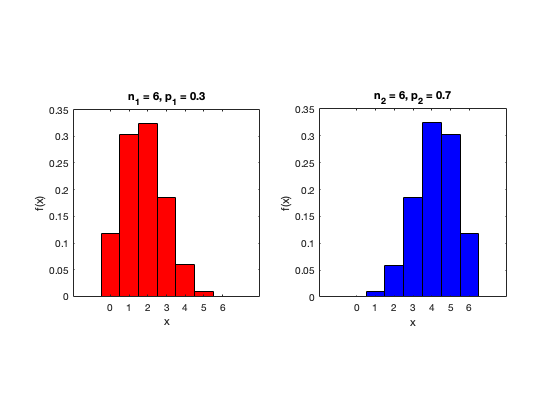

% X is a binomial random variablw with parameters (25, 0.2)
% In MATLAB we use `binocdf` or `binopdf`

prob_bino = binocdf(3,  25, 0.2); % the probability of X less than 3 
prob_bino2 = sum(binopdf(0:3, 25, 0.2)); % the sum of the PDF from 0 to 3 

% this two commands have the same return 

% Get the values for the domain, x. 
x = 0:6; 
% Get the values of the probability density function 
% First for n = 6, p = 0.3
n_1 = 6; p_1 = 0.3;
pdf1 = binopdf(x, n_1, p_1);
%Second for n = 6, p = 0.7
n_2 = 6; p_2 = 0.7;
pdf2 = binopdf(x, n_2, p_2);
% Do the plots 
subplot(1, 2, 1), bar(x, pdf1, 1, 'red')
title("n_1 = 6, p_1 = 0.3")
xlabel("x"), ylabel("f(x)")
axis square
subplot(1,2,2), bar(x, pdf2, 1,'blue')
title("n_2 = 6, p_2 = 0.7")
xlabel("x"), ylabel("f(x)")
axis square;

I have showed you how to calculate the PDF and CDF of Binomial Distribution, also how to draw the plot. 

## Poisson Distribution 

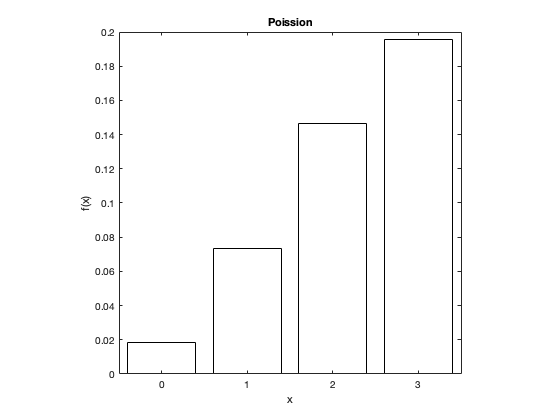

% this is another way to calculate the cdf and pdf 
% X = 3, lambda = 4
X = 0:3; lambda = 4;
prob_P = cdf("Poisson", 3, 4);
Pro_P2 = sum(pdf("Poisson",0:3, 4));
pdf_P = poisspdf(X, 4);
subplot(1,1,1), bar(X, pdf_P, 'white')
title("Poission")
xlabel("x"), ylabel("f(x)")
axis square

## Uniform Distribution 

We illustrate the uniform probability density function over the interval $(0, 10)$, along with the corresponding cumulative distribution function. The MATLAB Statistics and Machine Learning Toolbox function `unifpdf` and `unifcdf` are used to get the desired functions over the interval. 

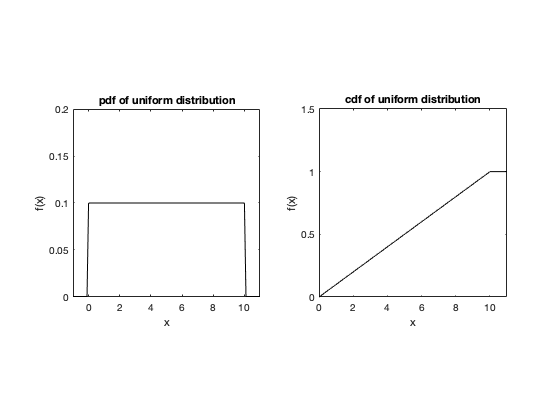

% get the domin over which we will
% evaluate the functions 
x = -1:.1:11;
% get the probability density function values at x
pdf = unifpdf(x, 0, 10);
% get the cumulate density function 
cdf = unifcdf(x, 0, 10);

%plot pdf & cdf
subplot(1,2,1);
plot(x,pdf, 'black');
title("PDF of uniform distribution");
xlabel("x"), ylabel("f(x)")
axis([-1 11 0 0.2]);
axis square

subplot(1,2,2);
plot(x,cdf, 'black');
title("CDF of uniform distribution");
xlabel("x"), ylabel("f(x)");
axis([0 11 0 1.5]);
axis square

## Normal Distribution

Similar to the uniform distribution, the functions `normpdf` and `normcdf` are avialbe in the MATLAB Statistics Toolbox for calculating the probability density function and culmulative distribution function for the normal. There is also another special function called `normspec` that determins the probability that a random varaible `X` assumes a vlue between two limits, where `X` is normally distriubted with mean $\mu$ and standard deviation $\sigma$. Ths function also plots the normal density, where the area between the specified limits is shaded.

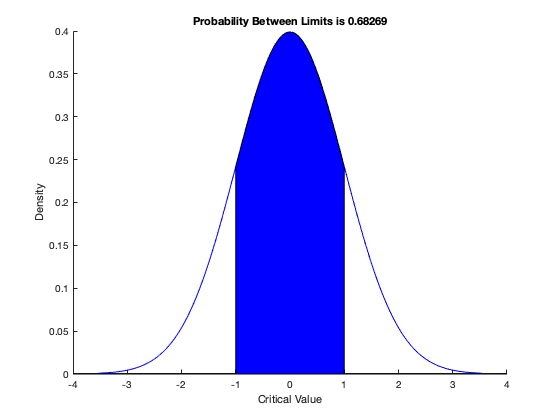

% set up the parameter for the normal distribution 
mu = 0;
sigma = 1;
% Set up the upper and lower limits, these are in the two element vector 'specs'
specs = [-1, 1];
prob = normspec(specs, mu, sigma, "inside");

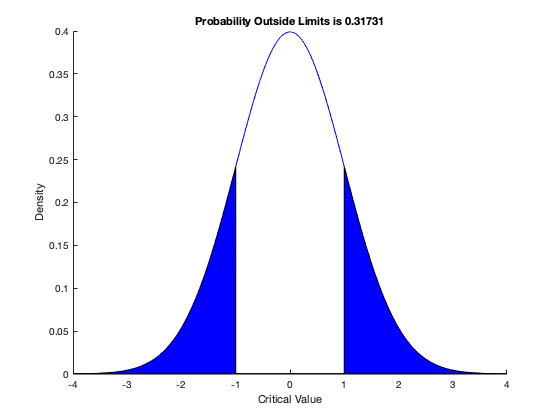

prob2 = normspec(specs, mu, sigma, "outside");

## Exponential Distribution

The time between arrival of vehicles at an intersection follows an exponential distirbution with a mean of $12$ seconds. What is the probability that the time between arrivals is $10$ seconds or less? We are given the average interatival time, so $\lambda =\frac{1}{12}$   . The required probability is 


$$P(X \leq 10) = 1 - e^{- \frac{1}{12} \times 10} \approx 0.57$$
 

You can calculate this using the MATLAB Statistics Toolbox function `expocdf(x, 1/lambda)` . NOte that this MATLAB function is based on a different definition of the exponentional probability density function, which is given by :


$$f(x;\mu) = \frac{1}{\mu} e^{-\frac{x}{\mu}}; \ \ x \leq 0 ; \mu > 0.$$
 

In the Computational Statistics Toolbox, we include a function called `csexpoc(x, \lambda)` 

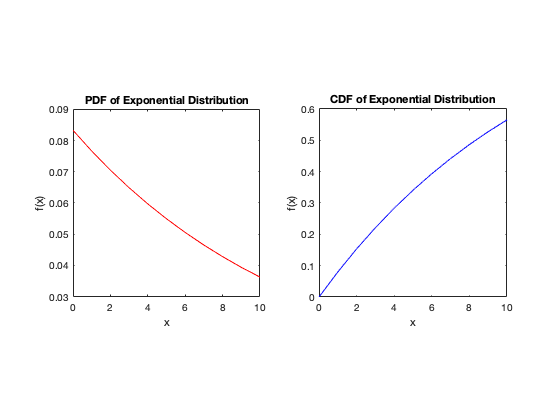

x = 0:10;
pdf = exppdf(x, 12);
cdf = expcdf(x, 12);

subplot(1,2,1);
plot(x,pdf,'red')
xlabel('x'); ylabel('f(x)');
title('PDF of Exponential Distribution');
axis square

subplot(1,2,2)
plot(x,cdf, 'blue')
xlabel('x'); ylabel('f(x)');
title('CDF of Exponential Distribution');
axis square

## Gamma

We plot the gamma probability density function for $\lambda = t = 1$ ( this should look like the exponential ), $\lambda = t = 3$. You can use the MATLAB Statistics Tool box function `gampdf(x, t, 1/lambda)` or the function `csgammp(x, t, \lambda)`

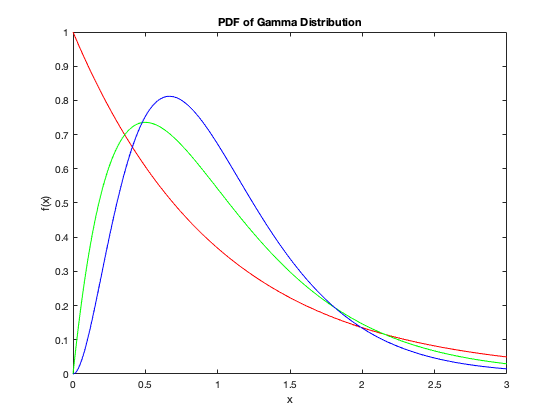

% get the domin over which to evaluate the functions
x = 0:.01:3;
% get the functions values for  different values of lambda 
y1 = gampdf(x, 1, 1/1);
y2 = gampdf(x, 2, 1/2);
y3 = gampdf(x, 3, 1/3);

%plot the functions 
subplot(1,1,1);
plot(x, y1,'r', x, y2, 'g', x, y3, 'b');
title('PDF of Gamma Distribution');
xlabel('x'); ylabel('f(x)')

## Chi-Square

If we difine a gamma distribution with $\lambda = 0.5$ and $t = \frac{v}{2}$ , with $v$ a positive interger, we can call this distribution **Chi-square Distribution. **

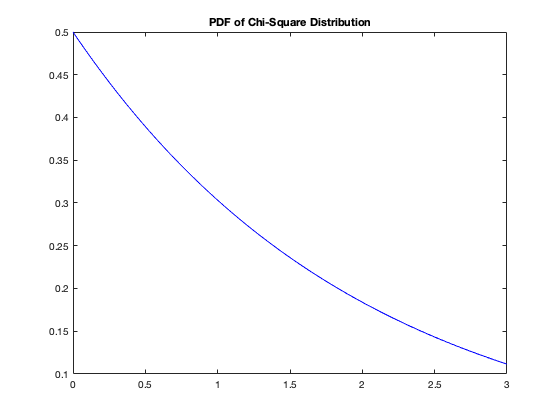

chi2_pdf = chi2pdf(x,2);
subplot(1,1,1);
plot(x,chi2_pdf,'b')
title('PDF of Chi-Square Distribution')

## Weibull Distribution

The exponential distribution has a constant hazard function, which is not generally the case for the Weibull distribution. The plot shows the hazard function for exponential (dashed line) and Weibull (solid line) distributions having the same mean life. The Weibull hazard rate here increases with age (a reasonable assumption).

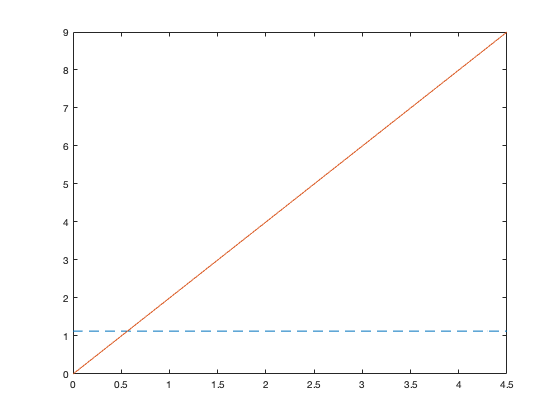

t = 0:0.1:4.5;
h1 = exppdf(t,0.8862)./(1-expcdf(t,0.8862));
h2 = wblpdf(t,1,2)./(1-wblcdf(t,1,2));
plot(t,h1,'--',t,h2,'-')

## Beta Distribution

We use the following MATLAB code to plot the beta density over the interval $(0, 1)$. We let $\alpha = \beta = 0.5#$ and $\alpha = \beta = 3$ 

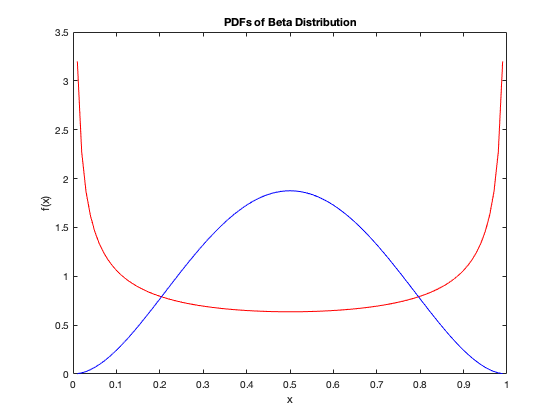

% get the domain over which to evaluate the density function 
x = 0.01:.01:.99;
%get the values for the density function 
y1 = betapdf(x, 0.5, 0.5);
y2 = betapdf(x, 3, 3);
%plot the results 
plot(x, y1, 'r', x, y2, 'b');
title('PDFs of Beta Distribution')
xlabel('x'); ylabel('f(x)')

## Multivariate Normal Distribution

We first provide the following MATLAB function to calculate the multivaraite normal probaility density function and illustrate its use in the bivariate case. The function is called `mvnpdf` to calculate the PDF and `mvncdf` to calculate the CDF. 

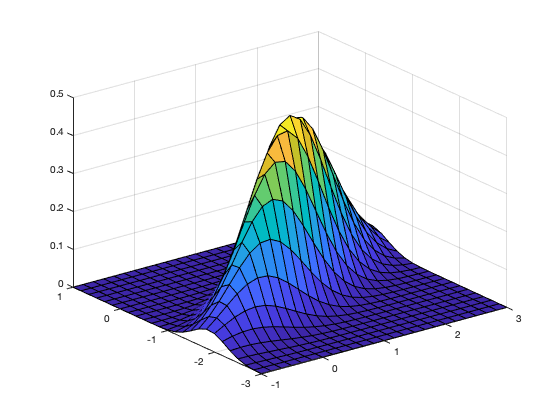

mu = [1 -1];
SIGMA = [.9 .4; .4 .3];
figure;
[X1,X2] = meshgrid(linspace(-1,3,25)',linspace(-3,1,25)');
X = [X1(:) X2(:)];
pdf = mvnpdf(X,mu,SIGMA);
surf(X1,X2,reshape(pdf,25,25));

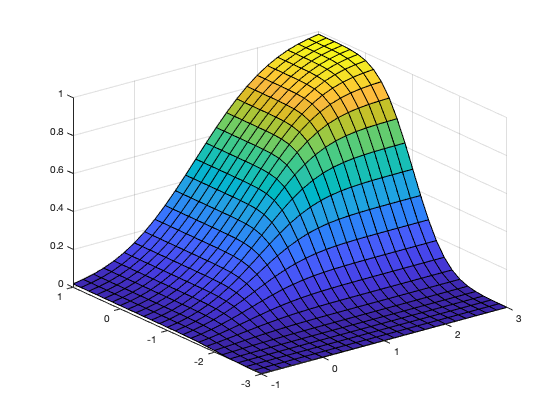

cdf = mvncdf(X,mu,SIGMA);
surf(X1,X2,reshape(cdf,25,25));